simtime = 20;
wcoeff = w1coeff;
wucoeff = w1ucoeff;
W = tf(wucoeff, wcoeff)

W =
 
    -11 s^4 - 75 s^3 - 98 s^2 + 404 s + 360
  -------------------------------------------
  s^5 + 2 s^4 - 17 s^3 - 38 s^2 + 172 s - 120
 
Continuous-time transfer function.



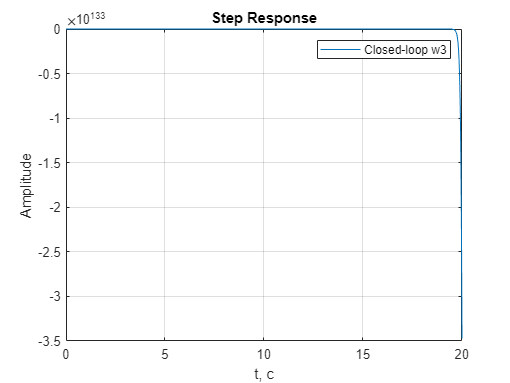

simul = sim("Task1.slx", simtime);
plot(simul.closed.Time, simul.closed.Data)
grid on
xlabel("t, с")
ylabel("Amplitude")
title("Step Response")
legend("Closed-loop w3")

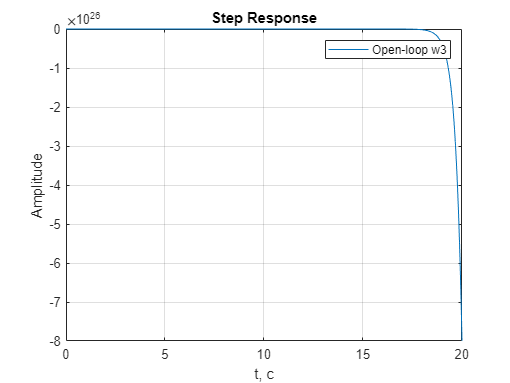

plot(simul.opened.Time, simul.opened.Data)
grid on
xlabel("t, с")
ylabel("Amplitude")
title("Step Response")
legend("Open-loop w3")

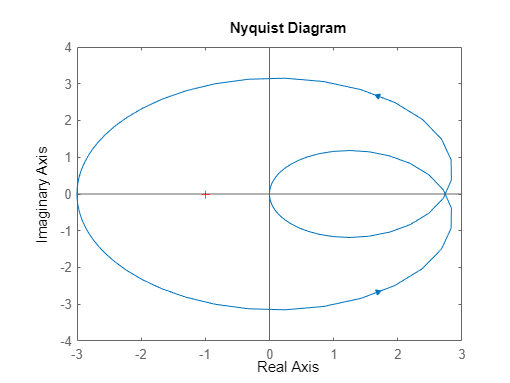

nyquist(W)